img_name = "watermelon-imgs/melon31.jpeg";

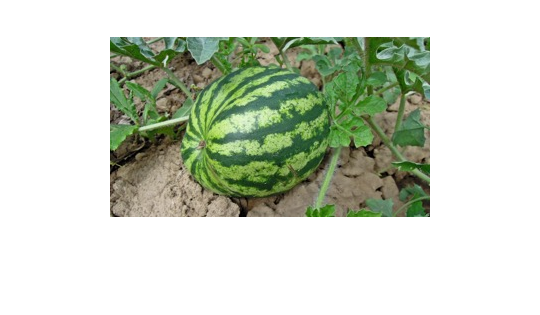

img = double(imread(img_name))./255;

mask = lasso_select(img, nan);

close

% label watermelon in the image
while true
    choice = get_input();
    
    if choice == 0 %stop
        break
    end
    
    curr_mask = lasso_select(img, mask);
    
    if choice == 1          %add
        mask = max(mask, curr_mask);
    elseif choice == 2      %remove
        mask = mask-mask.*curr_mask;
    end
    
end

% display the mask
imshow(img)
coord = mask2poly(mask, 'CW');
hold on 
ps = polyshape(uint16(coord(:,1)), uint16(coord(:,2)));

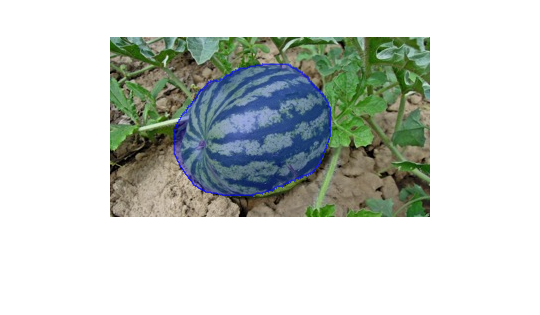

plot(ps, 'FaceAlpha', 0.3, 'FaceColor', 'b', ...
         'EdgeAlpha', 0.6, 'EdgeColor', 'b', 'LineWidth', 1);
hold off 

% save the labeled mask
imwrite(logical(mask), strcat(img_name, '_mask.tiff'));